ll tLive Script: Snell's Law from Fluid to Solid

Introduction

    In the provided GUI, we observed how changing the media and the angle of incidence affected how ultrasound waves are transmitted and reflected through a boundary. In the following Live Editor, I will walk you through the equations and functions used to generate that GUI to give you further intuition into Snell's Law in ultrasound applications. For further reading, please review Chapter 3: Acoustic Wave Propegation, in *Diagnostic Ultrasound Imaging: Inside Out* by Thomas Szabo. 

    As described in lecture, wave may be produced in longitudinal or shear forms, with both have different properties. Longitudinal waves may be thought of as pond ripples and are characterized by oscillating on the axis of propegation (the material compresses and expands as the wave travels). Shear waves are oscillations transverse to the direction of propegation and push the material up and down. Longitudinal waves may travel in any form of matter while shear waves may only travel through solids. This make sense because solids have an elastic, well-bound atomic structure, so if a solid is pertubed in anyway the material will attempt to return to its original state. Conversely, fluidics are catagorized by their loose atomic bounds. So while a fluid's atom's may be mildly compressed and expanded, it lacks to rigidity to support a shear wave.

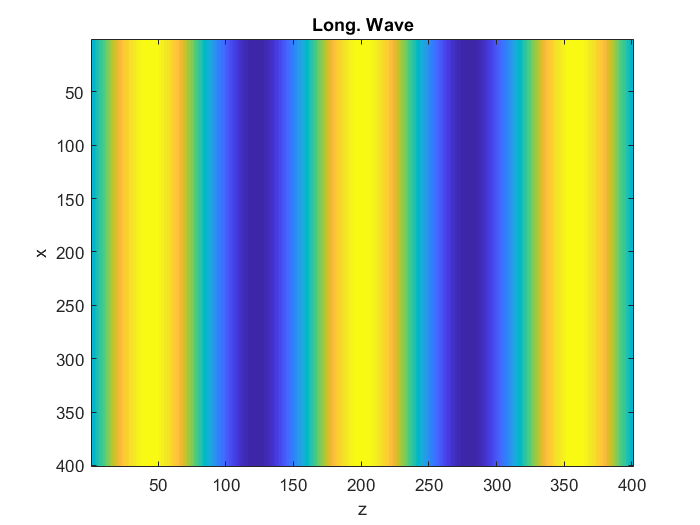

n = 400;
%Generate example Longitudinal Wave
[xx,yy] = meshgrid([-n/2:n/2]);
compress = cos(xx./25);
%Yellow Areas more compact material, blue areas less compact
imagesc(compress)
xlabel('z')
ylabel('x')
title('Long. Wave')

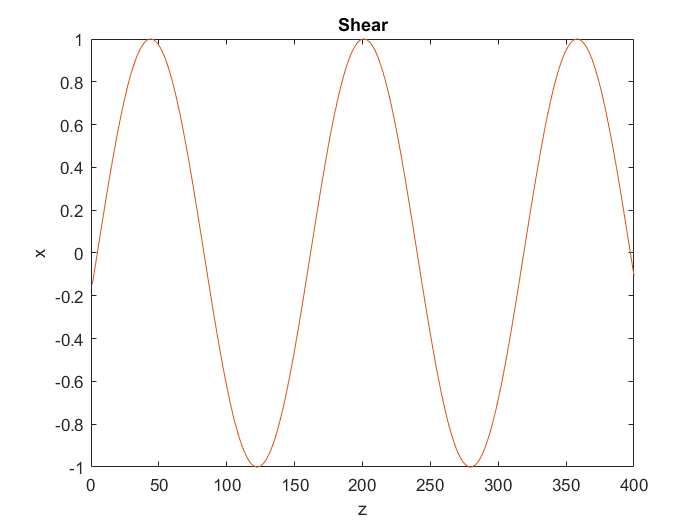

%Shear Wave
shear = cos(yy./25);
plot(shear)
xlabel('z')
ylabel('x')
title('Shear')
axis([0 400 -1 1])

Snell's Law

    In our experiment, we produce an ultrasound wave in a fluidic medium and saw how it interacted with the boundary to a solid medium. Intuitively, this means that our incident and reflected wave are Longitudinal, while our transmited wave is divided into a Longitudinal and Shear component. First, we may calculate the angle of light entering the new medium by using snell's law:


$$c_2 \sin \left(\theta_{\text{in}} \right)=c_1 \sin \left(\theta_{\text{out}} \right)$$


    Where c1 is the speed of sound in the first medium, $\theta_{\mathrm{in}}$ is the angle of incidence. c2 is the speed of sound in the second medium and $\theta_{\mathrm{out}}$ is the angle of refraction. Note, solids have different speeds of sound in the transverse and axial directions, so shear waves and longitudinal waves are refracted at different angles. Also, when solving snell's law for $\theta_{\text{out}}$, the value of $\frac{c_2 }{c_1 }\sin \left(\theta_{\text{in}} \right)$ may be greater then 1, meaning that snell's law is unsolvable. In this case, no light may enter the media and Total Internal Reflection (TIR) occurs. In the case of the GUI, you see when our ultrasound ray his this Critical Angle when no sound enters Medium 2 (the bottom part of the figure) and the reflection factor is ~1.

Boundary Conditions

    Now that we observe how light refracts into a medium, the last step we need to understand is how energy is transfered at a boundary. I will not reiterate the proof presented in the textbook here, but in short there are three coefficients we must calculate to determine the **intensities** of the **reflected wave**,** transmitted longitudinal wave **and **transmitted shear wave** respectively. Each equation will use the impedance of each boundary (Z), which is calculated by density*speed of sounds. Note, materials have different sound speeds for longitudinal waves and shear waves.

    To determine the percentage of the transmitted wave turned into shear or longitudinal elements, I point to the ratios presented in fig 3.11D in the textbook.

Shear Ratio=$n_s$: $2\ast \frac{\left({\left.\frac{2\pi f}{c_{2\mathrm{long}} }\right)}^2 \right.}{\left({\left.\frac{2\pi f}{c_{2\mathrm{shear}} }\right)}^2 \right.}$

Longitudinal Ratio = $n_l$ = 1-${\mathrm{Tf}}_s$

    Where f is the frequency, $c_{2\mathrm{long}}$ is the longitudinal speed and $c_{2\mathrm{shear}}$ is the shear speed. Since the frequency is uniform in this scenario, these ratios become a ratio of squared speeds. Note: the shear speed is always smaller then the longitudinal speed. The last value I will mention is the input impedance solved from the transmission line ananlogy for a shear-longitudinal transmission circuit presented in chapter 3. Please review Section 3.3.3 for the full derivation.


$$Z_{\text{in}} ={n_l }^2 \frac{Z_{2l} }{\cos \left(\theta_{2l} \right)}+{n_s }^2 \frac{Z_{2s} }{\cos \left(\theta_{2s} \right)}$$


    Where $Z_{2l}$ is the longitudinal impedance, $Z_{2s}$ is the shear impedance, $\theta_{2l}$ is the angle of the refracted longitudinal wave, and $\theta_{2s}$ is the refracted angle of the shear wave. Note: both angles are calculated by using snell's law with $c_2 =c_{2l} ,c_{2s}$ respectively. Also, this means Solids have two critical angles, one for Longitudinal Waves, one for Shear waves. One can be reflected and the other transmitted, please experiment with the GUI to see this behavior! A great example is use Nickel as Medium 1, Steel 4340 as Medium 2, and set the angle between 74-76 degrees. You will only see the shear wave as the longitudinal wave becomes a reflected mode.

    Using the above information, we may calculate the transmission factors through the following equations.

Transmitted Long. Intensity = $\tau_l$: $\frac{{{4n}_l }^2 \frac{Z_{1l} }{\mathrm{cos}\left(\theta_{\mathrm{in}} \right)}\frac{Z_{2l} }{\mathrm{cos}\left(\theta_{2l} \right)}}{{\left(\frac{Z_{1l} }{\mathrm{cos}\left(\theta_{\mathrm{in}} \right)}+Z_{\text{in}} \right)}^2 }$

Transmitted Shear Intensity = $\tau_s$: $\frac{{{4n}_s }^2 \frac{Z_{1l} }{\mathrm{cos}\left(\theta_{\mathrm{in}} \right)}\frac{Z_{2s} }{\mathrm{cos}\left(\theta_{2s} \right)}}{{\left(\frac{Z_{1l} }{\mathrm{cos}\left(\theta_{\mathrm{in}} \right)}+Z_{\text{in}} \right)}^2 }$

    Meaning that our reflection factor must equal:

r = $1-\tau_l -\tau_s$ = $\left(\frac{Z_{\text{in}} -\frac{Z_{1l} }{\mathrm{cos}\left(\theta_{\mathrm{in}} \right)}}{Z_{\text{in}} +\frac{Z_{1l} }{\mathrm{cos}\left(\theta_{\mathrm{in}} \right)}}\right)$

Code:

    Now that we understand some of the equations and notations, I will present the code utilized for the GUI and show you an example of how to perform these calculations!

    First, I will define a color map. This color map will hold the RGB values indicating the value of the reflected and refracted waves. **Please do not adjust this property and understand that it will act as a giant lookup table**.

jetColor = [0         0    0.5625;...
                     0         0    0.6250; ...
                     0         0    0.6875;...
                     0         0    0.7500;...
                     0         0    0.8125;...
                     0         0    0.8750;...
                     0         0    0.9375;...
                     0         0    1.0000;...
                     0    0.0625    1.0000;...
                     0    0.1250    1.0000;...
                     0    0.1875    1.0000;...
                     0    0.2500    1.0000;...
                     0    0.3125    1.0000;...
                     0    0.3750    1.0000;...
                     0    0.4375    1.0000;...
                     0    0.5000    1.0000;...
                     0    0.5625    1.0000;...
                     0    0.6250    1.0000;...
                     0    0.6875    1.0000;...
                     0    0.7500    1.0000;...
                     0    0.8125    1.0000;...
                     0    0.8750    1.0000;...
                     0    0.9375    1.0000;...
                     0    1.0000    1.0000;...
                0.0625    1.0000    0.9375;...
                0.1250    1.0000    0.8750;...
                0.1875    1.0000    0.8125;...
                0.2500    1.0000    0.7500;...
                0.3125    1.0000    0.6875;...
                0.3750    1.0000    0.6250;...
                0.4375    1.0000    0.5625;...
                0.5000    1.0000    0.5000;...
                0.5625    1.0000    0.4375;...
                0.6250    1.0000    0.3750;...
                0.6875    1.0000    0.3125;...
                0.7500    1.0000    0.2500;...
                0.8125    1.0000    0.1875;...
                0.8750    1.0000    0.1250;...
                0.9375    1.0000    0.0625;...
                1.0000    1.0000         0;...
                1.0000    0.9375         0;...
                1.0000    0.8750         0;...
                1.0000    0.8125         0;...
                1.0000    0.7500         0;...
                1.0000    0.6875         0;...
                1.0000    0.6250         0;...
                1.0000    0.5625         0;...
                1.0000    0.5000         0;...
                1.0000    0.4375         0;...
                1.0000    0.3750         0;...
                1.0000    0.3125         0;...
                1.0000    0.2500         0;...
                1.0000    0.1875         0;...
                1.0000    0.1250         0;...
                1.0000    0.0625         0;...
                1.0000         0         0;...
                0.9375         0         0;...
                0.8750         0         0;...
                0.8125         0         0;...
                0.7500         0         0;...
                0.6875         0         0;...
                0.6250         0         0;...
                0.5625         0         0;...
                0.5000         0         0];
            

    Below is the code utilized by the GUI, please fiddle and adjust as you see fit! Please note,** Longitudinal waves are indicated by solid arrows, Shear waves are dashed arrows**!

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%User Inputs, Please Adjust to your preference!
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%First Material: Water ~= Blood
speedLong1 = 1458; %m/s
speedShear1 = 0; %Fluids don't support shear waves
density1 = 1; %g/cm^3
z1l = speedLong1*density1;
degIn = 20; %Incident angle (degrees) -> Do not let exceed 89.9 degrees

%Second Material: Steel 4340 (let's say the person has a bone plate)
speedLong2 = 3960; %m/s
speedShear2 = 1670; %m/s;
density2 = 21.4; %g/cm^3
z2l = speedLong2*density2;
z2s = speedShear2*density2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Reflection/Refraction Angle and Intensity Calculations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%First I check the value c2/c1*sin(degIn) to see if the critical angle has been exceeded
transLong = sind(degIn)/speedLong1*speedLong2;
transShear = sind(degIn)/speedLong1*speedShear2;

%First Critical Angle -> Only shear wave transmits
if transLong >= 1
   degOutLong = 90; %No Longitudinal Wave Transmitted
   degOutShear = asind(transShear); %Still a Shear Wave
   nShear = 2*(1/c2Long)^2/(1/c2Shear)^2; %2*pi*f factor in each cancels
   nLong = 1-nShear;
   z1LongTheta = z1Long/cosd(app.degIn);
   z2LongTheta = 0; %No Angle Depedant Longitudinal Impedance
   z2ShearTheta = z2Shear/cosd(app.degOutShear);
   zIn = nLong^2*z2LongTheta+nShear^2*z2ShearTheta;
    
   %Reflection and Transmission
   Rf = (zIn-z1LongTheta)^2/(zIn+z1LongTheta)^2;
   Tf_l = 0;
   Tf_s = 4*z1LongTheta*nShear^2*z2ShearTheta/(z1LongTheta+zIn)^2; 

%Second Critical Angle -> Total Reflection Occurs
elseif transShear >= 1
    Rf = 1;
    Tf_l = 0;
    Tf_s = 0;
    degOutLong = 0;
    degOutShear = 0;
    

%Else calculate new angles, and appropriate intensities
else
    degOutLong = asind(transLong) %Transmistted Longitudinal angle
    degOutShear = asind(transShear) %Transmitted Shear Angle
    nShear = 2*(1/speedLong2)^2/(1/speedShear2)^2; %Percent transmitted wave converted into a shear wave
    nLong = 1-nShear; %Percent Longitudinal Wave
    
    %Calculate Angle dependant impedances
    z1LongTheta = z1l/cosd(degIn);
    z2LongTheta = z2l/cosd(degOutLong);
    z2ShearTheta = z2s/cosd(degOutShear);
    zIn = nLong^2*z2LongTheta+nShear^2*z2ShearTheta;
    
    %Reflection and Transmission
    Rf = (zIn-z1LongTheta)^2/(zIn+z1LongTheta)^2 %Transmitted Shear
    Tf_l = 4*z1LongTheta*nLong^2*z2LongTheta/(z1LongTheta+zIn)^2 %Transmitted Longitudinal
    Tf_s = 4*z1LongTheta*nShear^2*z2ShearTheta/(z1LongTheta+zIn)^2 %Transmitted Shear
end

degOutLong = 68.2707

degOutShear = 23.0635

Rf = 0.9398

Tf_l = 0.0573

Tf_s = 0.0030


%%%%%%%%%%
%Draw Axes
%%%%%%%%%%

%Draw axes lines
figure; %Define a new figure
hold on; %This allows us to draw on the same figure until hold is turned off
line([-1 1], [0 0],'LineWidth',2,'Color','k'); %x-axis
line([0 0], [-1 1],'LineWidth',2,'LineStyle','--'); %y-axis

%%%%%%%%%%%%%%%%%%%%%%%
%Draw Arrows and Angles
%%%%%%%%%%%%%%%%%%%%%%%

%First, I adjust the calculated angles so the arrows will appear in the correct quadrant of the graph
inc = 90+degIn %Incident Angle->second quadrant

inc = 110

rfl = 90-degIn %Reflected Angle->first quadrant

rfl = 70

rfr = 270+degOutLong %Refracted Longitudinal Angle->fourth quadrant

rfr = 338.2707

shear = 270+degOutShear %Refracted Shear Angle->Forth Quadrant

shear = 293.0635

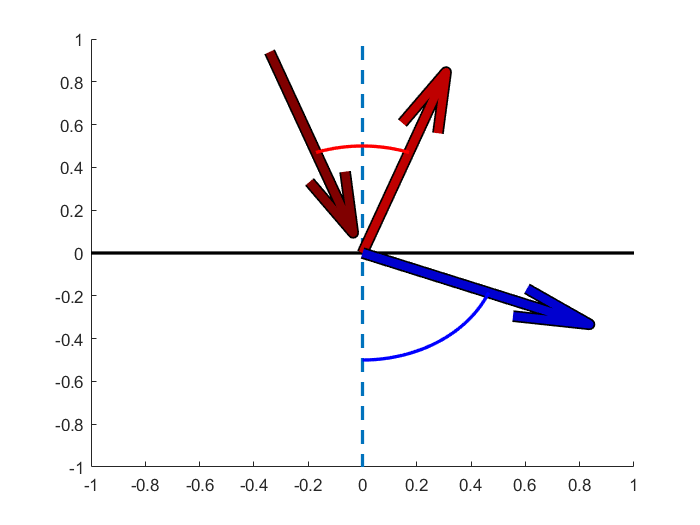

 r = 0.5;
 
%Define a line covering how far I want the angles to draw
theta_rfl = linspace(rfl,inc,100); %Angle line between reflected and incident
theta_rfr = linspace(270,rfr,100); %Angle between y-axis and Longitudinal Transmitted
theta_shear = linspace(270,shear,100);%Angle between y-axis and Shear Transmitted

%The arrow's color will be based on the reflected and refracted intensity values
rflRGB = jetColor(round(Rf*63)+1,:);
rfrRGB = jetColor(round(Tf_l*63)+1,:);
shearRGB = jetColor(round(Tf_s*63)+1,:);

%Draw Incident Arrow
%I outline the longitudinal waves in black by drawing a larger black arrow first
quiver(cosd(inc), sind(inc), -cosd(inc), -sind(inc), ...
'Color','k', ...
'LineWidth',7, ...
'MaxHeadSize',1);
quiver(cosd(inc), sind(inc), -cosd(inc), -sind(inc), ...
'Color',jetColor(end,:), ...
'LineWidth',5, ...
'MaxHeadSize',1);

%Draw Reflected Angle
if Rf > 0.01 % If the value is under 1% I don't bother drawing that arrow for almost no power is retained in that wave
     quiver(0, 0, cosd(rfl), sind(rfl), ...
    'Color','k', ...
    'LineWidth',7, ...
    'MaxHeadSize',1);
    quiver(0, 0, cosd(rfl), sind(rfl), ...
    'Color',rflRGB, ...
    'LineWidth',5, ...
    'MaxHeadSize',1);
    %Draw Angle Line
    plot(r*cosd(theta_rfl),r*sind(theta_rfl),'LineWidth',2,'Color','r');
end

%Transmitted Longitude Arrow
if Tf_l > 0.01
    quiver(0, 0, cosd(rfr), sind(rfr), ...
    'Color','k', ...
    'LineWidth',7, ...
    'MaxHeadSize',1);
    quiver(0, 0, cosd(rfr), sind(rfr), ...
    'Color',rfrRGB, ...
    'LineWidth',5, ...
    'MaxHeadSize',1);
    %Draw Angle Line
    plot(r*cosd(theta_rfr),r*sind(theta_rfr),'LineWidth',2,'Color','b');
end


%Transmitted Shear Arrow
if Tf_s > 0.01
     quiver(0, 0, cosd(shear), sind(shear), ...
    'Color',shearRGB, ...
    'LineWidth',5, ...
    'MaxHeadSize',1, ...
    'LineStyle','--');
    %Draw Angle Line
    plot((r+0.15)*cosd(theta_shear),(r+0.15)*sind(theta_shear),'LineWidth',2,'Color','k');
end

    